# MATLAB function for map information exported from drivingScenarioDesigner

This script shows how to export the map information file "scenario_map_v1.m" of the scenario from drivingScenarioDesigner for 2D and 3D visualization.

- First, open app "Driving Scenario Designer", and click button "open"  to open "scr\Scripts\Load Data\map_v1\map_v1.mat"  in the app.

     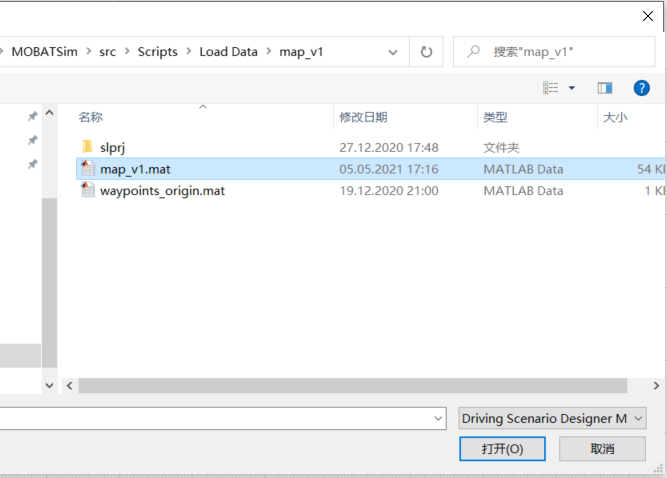

      2. The left side are the parameters of the chosen road section. If the road needs to be changed from single lane to double lane, just change the "Number of Lanes" from 1 to 2.

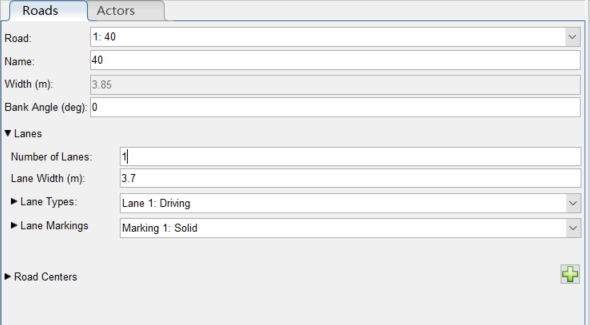

3. Click "Export", and click "MATLAB Function".

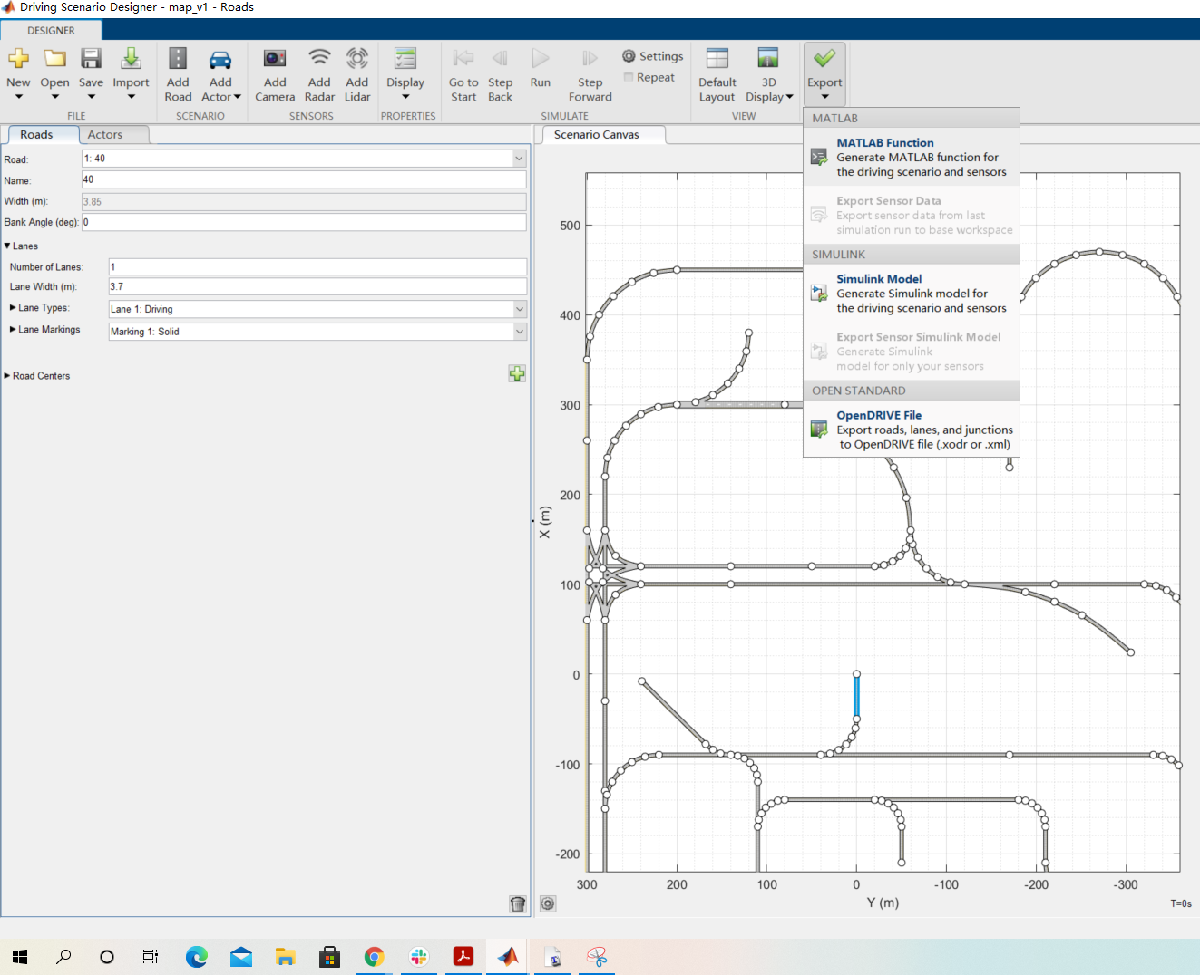

The exported function of the scenario contains the data of the map for visualization.

function scenario = map_v1()
% createDrivingScenario Returns the drivingScenario defined in the Designer

% Generated by MATLAB(R) 9.9 (R2020b) and Automated Driving Toolbox 3.2 (R2020b).
% Generated on: 21-May-2021 22:17:45

% Construct a drivingScenario object.
scenario = drivingScenario;

% Add all road segments
roadCenters = [0 0 0;
    -50 0 0];
laneSpecification = lanespec(1, 'Width', 3.7);
road(scenario, roadCenters, 'Lanes', laneSpecification, 'Name', '40');
......
    

4. Save the function in folder Misc/ BirdEyeView_Visualization as a .m file "scenario_map_v1.m", and change the name of the function to the same with file function.

function scenario = scenario_map_v1()

5. If one of the roads needs to be shifted for a distance, just change the coordinate of the corresponding roadCenters. This change is only for visualization, it doesn't change the MOBATSim map.

roadCenters = [300 -100 0;
    300 80 0];
roadCenters(:,1) = roadCenters(:,1)+1.85;% add 1.85 to x to shift the road
laneSpecification = lanespec(2, 'Width', 3.7);
road(scenario, roadCenters, 'Lanes', laneSpecification, 'Name', 'Road36');

6. The map is loaded in "run_Bird_eye_view.m" and "openScenarioInApp.m" for 2D and 3D visualization with following:

MOBATKent_Scenario = scenario_map_v1();

7. If the map is newly updated or changes, just repeat the above procedure to update the scenario for  visualization.